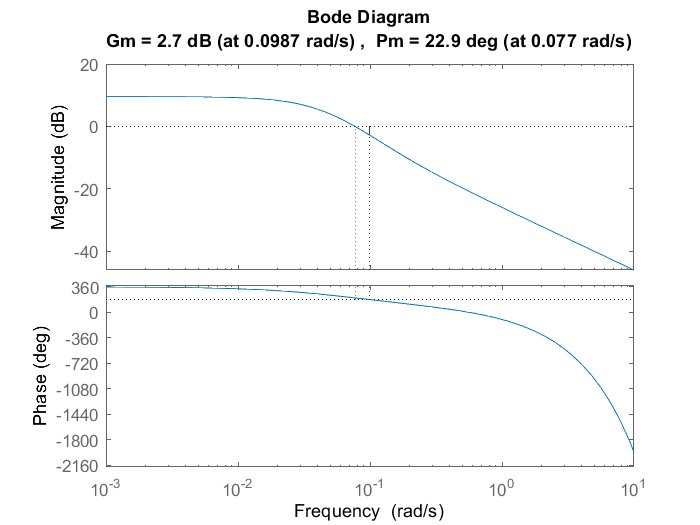

clear
close all
clc

B1 = 209;
B2 = 446;
G = 2018;

V = mod(B1 + B2 + 2*G, 5) + 1;

s = tf('s');
G = (-0.05*s + 0.0075) / (s + 0.05)^2 * exp(-3.6*s);

margin(G)

## PI linearni kontroler

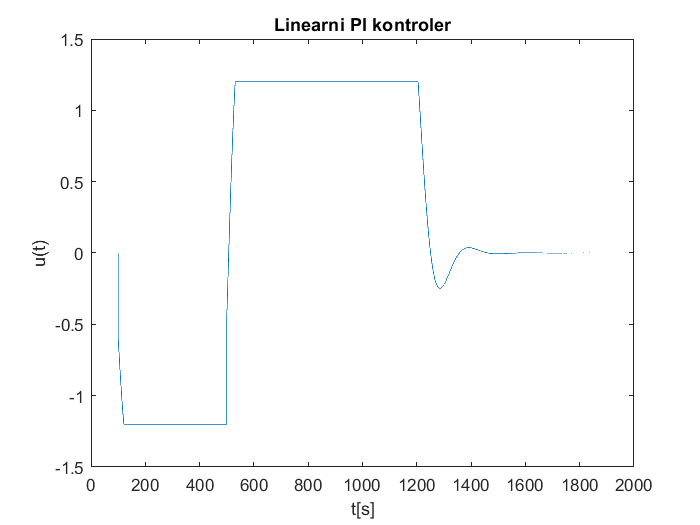


sel = 1;
sel1 = 1;
poremecaj = 0;

Kp = 0.1667;
Ti = 1 / 0.05;  

% sluzi samo da se program izvrsi
Ku_cap = 1;
Kp_cap = 1;
Kd_cap = 1;

out = sim('projekat2.slx');

figure
plot(out.tout, out.u)
xlabel('t[s]')
ylabel('u(t)')
title('Linearni PI kontroler')

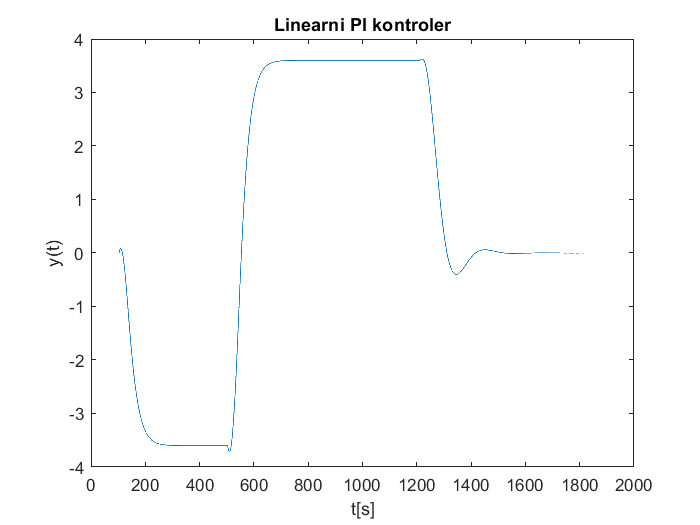


figure
plot(out.tout, out.y)
xlabel('t[s]')
ylabel('y(t)')
title('Linearni PI kontroler')


% Odredjivanje maksimalnog inkrementa signala upravljanja
du_max = 0;

for i = 2 : length(out.u)
    d = out.u(i) - out.u(i-1);
    if d > du_max
        du_max = d;
    end
end

%du_max = 0.7464

## Fazi PI kontroler

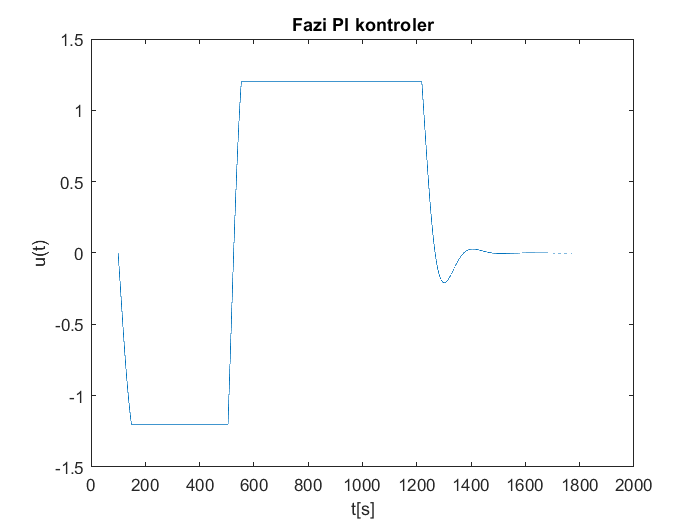


sel = 2;
out = sim('projekat2.slx');

% Inicijalni izbor parametara
% Ku_cap = du_max / 2 / 0.1;
% Kp_cap = Kp / Ti / Ku_cap;
% Kd_cap = Kp / Ku_cap;

% blaga povrs
lin_fpd_blaga = readfis('lin_fpd_blaga.fis');
Ku_cap = du_max / 2 / 0.1;
Kp_cap = Kp / Ti / Ku_cap * 1.2;
Kd_cap = Kp/Ku_cap * 1.2;

figure
plot(out.tout, out.u)
xlabel('t[s]')
ylabel('u(t)')
title('Fazi PI kontroler')

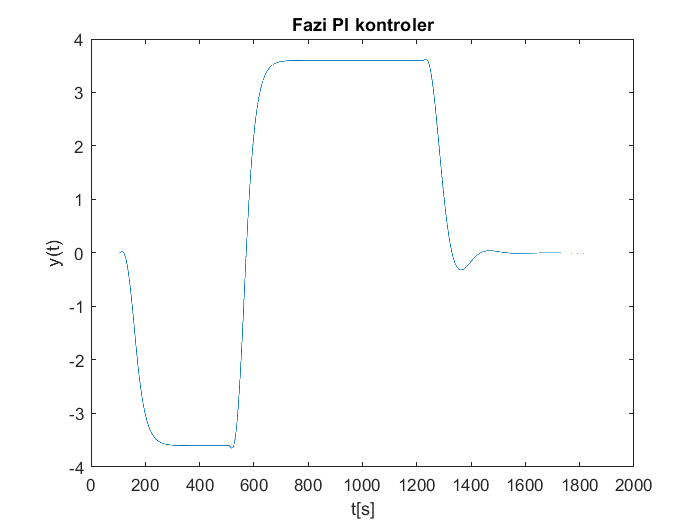


figure
plot(out.tout, out.y)
xlabel('t[s]')
ylabel('y(t)')
title('Fazi PI kontroler')


figure
plot(out.tout, out.e_cap)
xlabel('t[s]')
ylabel('e_cap(t)')
title('Fazi PI kontroler')

figure
plot(out.tout, out.ed_cap)
xlabel('t[s]')
ylabel('ed_cap(t)')
title('Fazi PI kontroler')


% % naborana povrs
% 
% lin_fpd_naboran = readfis('lin_fpd_naboran.fis');
% Ku_cap = du_max / 2 / 0.1;
% Kp_cap = Kp / Ti / Ku_cap * 11;
% Kd_cap = Kp/Ku_cap * 7;
% 

% % strma povrs
% lin_fpd_strma = readfis('lin_fpd_strma.fis');
% Ku_cap = du_max / 2 / 0.1;
% Kp_cap = Kp / Ti / Ku_cap * 1;
% Kd_cap = Kp/Ku_cap * 1;


## Ponasanje pri delovanju poremecaja

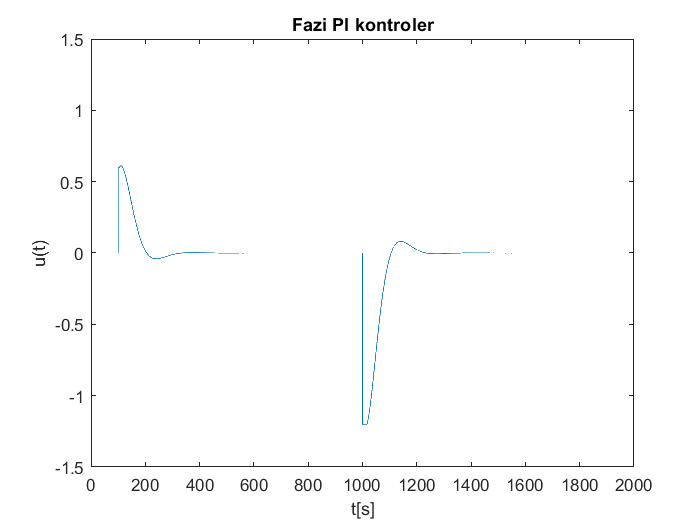


poremecaj = 0.6;
sel = 2;
sel1 = 2;
out = sim('projekat2.slx');

figure
plot(out.tout, out.u)
xlabel('t[s]')
ylabel('u(t)')
title('Fazi PI kontroler')
ylim([-1.5 1.5])

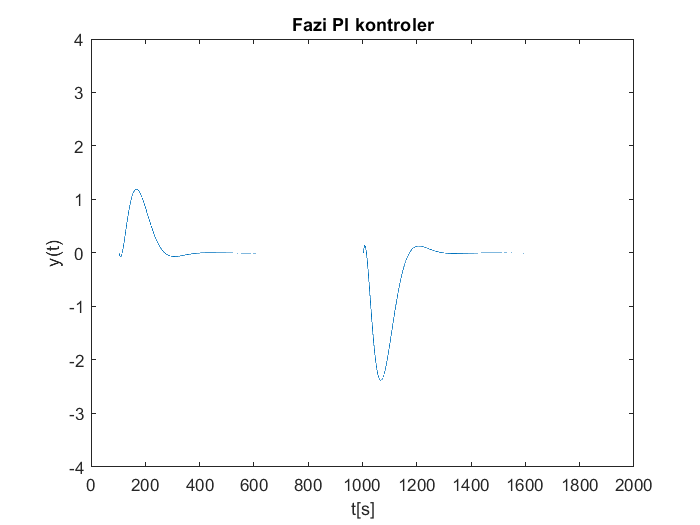


figure
plot(out.tout, out.y)
xlabel('t[s]')
ylabel('y(t)')
title('Fazi PI kontroler')
ylim([-4 4])

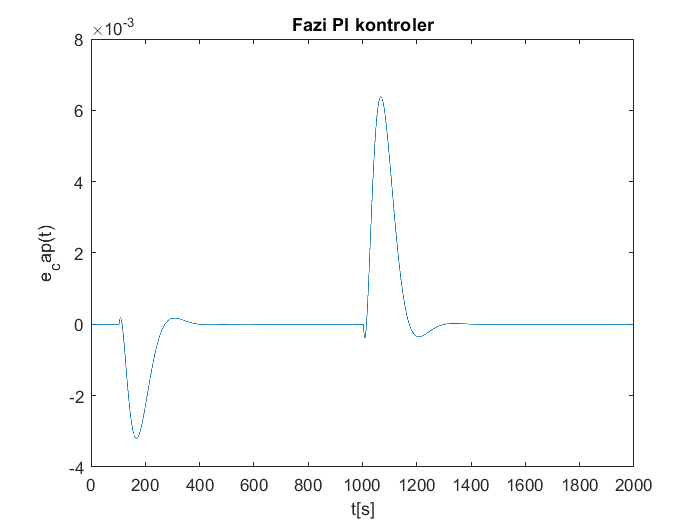


figure
plot(out.tout, out.e_cap)
xlabel('t[s]')
ylabel('e_cap(t)')
title('Fazi PI kontroler')

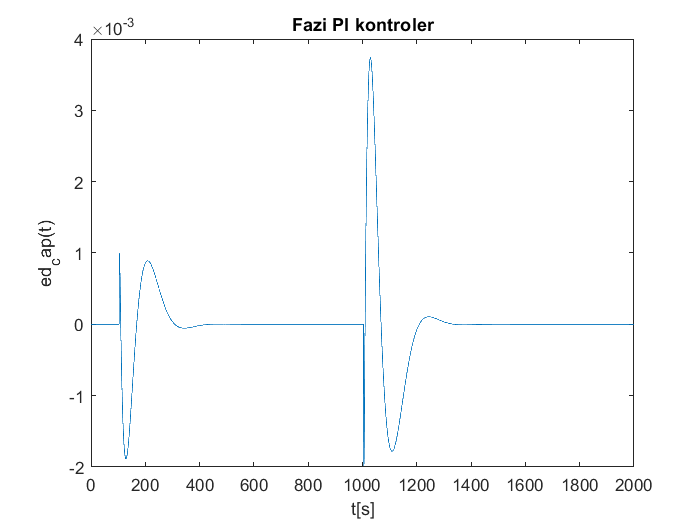


figure
plot(out.tout, out.ed_cap)
xlabel('t[s]')
ylabel('ed_cap(t)')
title('Fazi PI kontroler')